1. (8%) Let $x[n]=n(0.9)^nu[n],$

(a) Determine the DTFT$\tilde{X}(e^{j\omega})$ of $x[n]$. Please write your calculations and answer on your .mlx file. 

-sol-


$$\tilde{X}(e^{j\omega})=-j\frac{d}{d\omega}\frac{1}{1-0.9e^{-j\omega}}=\frac{0.9e^{-j\omega}}{(1-0.9e^{-j\omega})^2}$$


(b) Choose first $N = 20$ samples of $x[n]$ and compute the approximate DTFT $\tilde{X}_N(e^{j\omega})$ using the fft function. Plot magnitudes of $\tilde{X}(e^{j\omega})$ and $\tilde{X}_N(e^{j\omega})$ in one plot and compare your results.

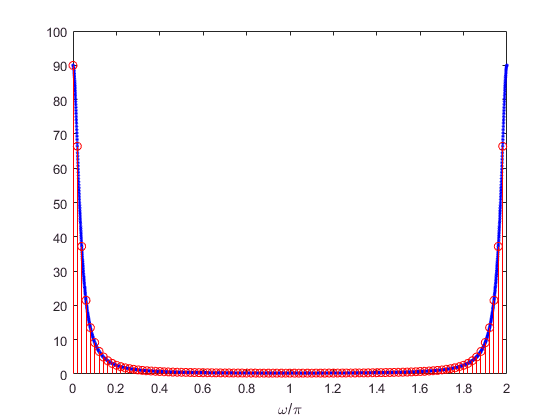

clc;clear;close all;

om=linspace(0, 2*pi, 3600);
N=20;
n=0:N-1;
range = 2/N*(0:N-1);

x=n.*0.9.^n;
XN=fft(x);
X=0.9*exp(-1j*om)./(1-0.9*exp(-1j*om)).^2;

figure(1)
plot(om/pi, abs(X),'.b')
hold on
stem(range, abs(XN), 'r')
xlabel("\omega/\pi")

(c) Repeat part (b) using $N = 50$. 

clc;clear;close all;

om=linspace(0, 2*pi, 3600);
N=50;
n=0:N-1;
range = 2/N*(0:N-1);

x=n.*0.9.^n;
XN=fft(x);
X=0.9*exp(-1j*om)./(1-0.9*exp(-1j*om)).^2;

figure(1)
plot(om/pi, abs(X),'.b')
hold on
stem(range, abs(XN), 'r')
xlabel("\omega/\pi")

(d) Repeat part (b) using $N = 100$.

clc;clear;close all;

om=linspace(0, 2*pi, 3600);
N=100;
n=0:N-1;
range = 2/N*(0:N-1);

x=n.*0.9.^n;
XN=fft(x);
X=0.9*exp(-1j*om)./(1-0.9*exp(-1j*om)).^2;

figure(1)
plot(om/pi, abs(X),'.b')
hold on
stem(range, abs(XN), 'r')
xlabel("\omega/\pi")

2. (10%)Let $x[n]=x_1[n]+jx_2[n]$ where sequences $x_1[n] $ and $x_2[n]$ are real-valued. 

(a) Show that $X_1[k]=X^{cce}[k]$ and $jX_2[k]=X^{cco}[k]$. Please write your calculations and answer on your .mlx file. 

pf: Claim that $x^*[n]\leftrightarrow X^*[<-k>_N]$

proof of claim: 


$$\sum_{n=0}^{N-1}x^*[n]e^{-j\frac{2\pi}{N}kn}\\
=\bigg(\sum_{n=0}^{N-1}x[n]e^{j\frac{2\pi}{N}kn}\bigg)^*\\
=\bigg(\sum_{n=0}^{N-1}x^*[n]e^{-j\frac{2\pi}{N}(-k)n}\bigg)^*\\
=X^*[-k]\\
=X^*[<-k>_N] \text{ by (7.102)}$$


So

 
$$x_1[n]=\frac{1}{2}(x[n]+x^*[n])\\
\leftrightarrow X_1[k]=\frac{1}{2}(X[k]+X^*[<-k>_N])=X^{cce}[k]$$


and 


$$x_2[n]=\frac{1}{2}(x[n]-x^*[n])\\
\leftrightarrow X_1[k]=\frac{1}{2}(X[k]-X^*[<-k>_N])=X^{cco}[k]$$


(b) Write a MATLAB function 

[X1,X2] = tworealDFTs(x1,x2)  

that implements the results in part (a). 

(c) Verify your function on the following two sequences: $x_1[n]=(0.9)^n$, $x_2[n]=(1-0.8^n)$; $0\leq n\leq49$

clc;clear;close all;

n=0:49;
x1=0.9.^n;
x2=1-0.8.^n;

[X1, X2]=tworealDFTs(x1, x2)

X1 =    9.9485 + 0.0000i   4.4039 - 4.6384i   1.9176 - 3.3459i   1.1903 - 2.4164i   0.9037 - 1.8541i   0.7646 - 1.4876i   0.6873 - 1.2311i   0.6401 - 1.0411i   0.6092 - 0.8941i   0.5880 - 0.7763i   0.5728 - 0.6792i   0.5616 - 0.5972i   0.5531 - 0.5266i   0.5466 - 0.4647i   0.5414 - 0.4096i   0.5374 - 0.3599i   0.5341 - 0.3144i   0.5315 - 0.2725i   0.5294 - 0.2333i   0.5277 - 0.1963i   0.5264 - 0.1611i   0.5253 - 0.1273i   0.5246 - 0.0946i   0.5240 - 0.0627i   0.5237 - 0.0312i   0.5236 + 0.0000i   0.5237 + 0.0312i   0.5240 + 0.0627i   0.5246 + 0.0946i   0.5253 + 0.1273i   0.5264 + 0.1611i   0.5277 + 0.1963i   0.5294 + 0.2333i   0.5315 + 0.2725i   0.5341 + 0.3144i   0.5374 + 0.3599i   0.5414 + 0.4096i   0.5466 + 0.4647i   0.5531 + 0.5266i   0.5616 + 0.5972i   0.5728 + 0.6792i   0.5880 + 0.7763i   0.6092 + 0.8941i   0.6401 + 1.0411i   0.6873 + 1.2311i   0.7646 + 1.4876i   0.9037 + 1.8541i   1.1903 + 2.4164i   1.9176 + 3.3459i   4.4039 + 4.6384i


X2 =   45.0001 + 0.0000i  -3.9209 + 1.9056i  -2.4940 + 2.2040i  -1.6814 + 1.9329i  -1.2566 + 1.6199i  -1.0209 + 1.3607i  -0.8800 + 1.1562i  -0.7903 + 0.9940i  -0.7300 + 0.8630i  -0.6877 + 0.7550i  -0.6571 + 0.6642i  -0.6343 + 0.5863i  -0.6169 + 0.5186i  -0.6034 + 0.4587i  -0.5928 + 0.4051i  -0.5843 + 0.3565i  -0.5775 + 0.3118i  -0.5721 + 0.2705i  -0.5677 + 0.2317i  -0.5641 + 0.1951i  -0.5613 + 0.1602i  -0.5592 + 0.1267i  -0.5575 + 0.0942i  -0.5564 + 0.0624i  -0.5558 + 0.0311i  -0.5555 + 0.0000i  -0.5558 - 0.0311i  -0.5564 - 0.0624i  -0.5575 - 0.0942i  -0.5592 - 0.1267i  -0.5613 - 0.1602i  -0.5641 - 0.1951i  -0.5677 - 0.2317i  -0.5721 - 0.2705i  -0.5775 - 0.3118i  -0.5843 - 0.3565i  -0.5928 - 0.4051i  -0.6034 - 0.4587i  -0.6169 - 0.5186i  -0.6343 - 0.5863i  -0.6571 - 0.6642i  -0.6877 - 0.7550i  -0.7300 - 0.8630i  -0.7903 - 0.9940i  -0.8800 - 1.1562i  -1.0209 - 1.3607i  -1.2566 - 1.6199i  -1.6814 - 1.9329i  -2.4940 - 2.2040i  -3.9209 - 1.9056i


X=fft(x1)

X =    9.9485 + 0.0000i   4.4039 - 4.6384i   1.9176 - 3.3459i   1.1903 - 2.4164i   0.9037 - 1.8541i   0.7646 - 1.4876i   0.6873 - 1.2311i   0.6401 - 1.0411i   0.6092 - 0.8941i   0.5880 - 0.7763i   0.5728 - 0.6792i   0.5616 - 0.5972i   0.5531 - 0.5266i   0.5466 - 0.4647i   0.5414 - 0.4096i   0.5374 - 0.3599i   0.5341 - 0.3144i   0.5315 - 0.2725i   0.5294 - 0.2333i   0.5277 - 0.1963i   0.5264 - 0.1611i   0.5253 - 0.1273i   0.5246 - 0.0946i   0.5240 - 0.0627i   0.5237 - 0.0312i   0.5236 + 0.0000i   0.5237 + 0.0312i   0.5240 + 0.0627i   0.5246 + 0.0946i   0.5253 + 0.1273i   0.5264 + 0.1611i   0.5277 + 0.1963i   0.5294 + 0.2333i   0.5315 + 0.2725i   0.5341 + 0.3144i   0.5374 + 0.3599i   0.5414 + 0.4096i   0.5466 + 0.4647i   0.5531 + 0.5266i   0.5616 + 0.5972i   0.5728 + 0.6792i   0.5880 + 0.7763i   0.6092 + 0.8941i   0.6401 + 1.0411i   0.6873 + 1.2311i   0.7646 + 1.4876i   0.9037 + 1.8541i   1.1903 + 2.4164i   1.9176 + 3.3459i   4.4039 + 4.6384i


X=fft(x2)

Y =   45.0001 + 0.0000i  -3.9209 + 1.9056i  -2.4940 + 2.2040i  -1.6814 + 1.9329i  -1.2566 + 1.6199i  -1.0209 + 1.3607i  -0.8800 + 1.1562i  -0.7903 + 0.9940i  -0.7300 + 0.8630i  -0.6877 + 0.7550i  -0.6571 + 0.6642i  -0.6343 + 0.5863i  -0.6169 + 0.5186i  -0.6034 + 0.4587i  -0.5928 + 0.4051i  -0.5843 + 0.3565i  -0.5775 + 0.3118i  -0.5721 + 0.2705i  -0.5677 + 0.2317i  -0.5641 + 0.1951i  -0.5613 + 0.1602i  -0.5592 + 0.1267i  -0.5575 + 0.0942i  -0.5564 + 0.0624i  -0.5558 + 0.0311i  -0.5555 + 0.0000i  -0.5558 - 0.0311i  -0.5564 - 0.0624i  -0.5575 - 0.0942i  -0.5592 - 0.1267i  -0.5613 - 0.1602i  -0.5641 - 0.1951i  -0.5677 - 0.2317i  -0.5721 - 0.2705i  -0.5775 - 0.3118i  -0.5843 - 0.3565i  -0.5928 - 0.4051i  -0.6034 - 0.4587i  -0.6169 - 0.5186i  -0.6343 - 0.5863i  -0.6571 - 0.6642i  -0.6877 - 0.7550i  -0.7300 - 0.8630i  -0.7903 - 0.9940i  -0.8800 - 1.1562i  -1.0209 - 1.3607i  -1.2566 - 1.6199i  -1.6814 - 1.9329i  -2.4940 - 2.2040i  -3.9209 - 1.9056i


3. (9%) Let $x_1[n]=\{1_{n=0}, 2, 3, 4, 5\}$ be a 5-point sequence and let $x_2[n]=\{2_{n=0}, -1, 1, -1\}$ be a 4-point sequence.

(a) Determine $x_1[n](5)x_2[n]$ using hand calculations. Please write your calculations and 

answer on your .mlx file. 

-sol-


$$1\times2+2\times0+3\times(-1)+4\times1+5\times(-1)=-2\\
1\times(-1)+2\times2+3\times0+4\times(-1)+5\times1=4\\
1\times1+2\times(-1)+3\times2+4\times0+5\times(-1)=0\\
1\times(-1)+2\times1+3\times(-1)+4\times2+5\times0=6\\
1\times0+2\times(-1)+3\times1+4\times(-1)+5\times2=7\\$$


(b) Verify your calculations in (a) using the circonv function.

clc;clear;close all;

x1=[1, 2, 3, 4, 5];
x2=[2, -1, 1, -1, 0];

cconv(x1,x2,5)

ans =    -2.0000    4.0000    0.0000    6.0000    7.0000


(c) Verify your calculations in (a) by computing the DFTs and IDFT. 

X=fft(x1,5).*fft(x2,5);
ifft(X)

ans =    -2.0000    4.0000    0.0000    6.0000    7.0000


(8%) Let $x_1[n]$ be an $N_1$-point and $x_2[n]$ be an $N_2$-point sequence. Let $N ≥ \max(N_1,N_2)$. Their $N$-point circular convolution is shown to be equal to the aliased version of their linear convolution in (7.209) in Program Assignment 3. This result can be used to compute the circular convolution via the linear convolution. 

(a) Develop a MATLAB function 

y = lin2circonv(x,h) 

that implements this approach. 

(b) For $x[n]=\{1_{n=0}, 2, 3, 4\}$ and $h[n]=\{1_{n=0}, -1, 1, -1\}$determine their 4-point circular convolution using the lin2circonv function and verify using the circonv function. 

clc;clear;close all;

x=[1, 2, 3, 4];
h1=[1, -1, 1, -1];

lin2circonv(x,h1,4) 

ans =     -2     2    -2     2


cconv(x,h1,4)

ans =     -2     2    -2     2


5. (15%) Let a 2D filter impulse response $h[m,n]$ be given by 


$$h[m,n]=
    \left\{\begin{array}{ll} 
   \frac{1}{2\pi\sigma^2}e^-\frac{m^2+n^2}{2\sigma^2}, & -128\leq m,n\leq127 \\
    0, & \text{Otherwise}
    \end{array}\right. $$


where $σ$ is a parameter. For this problem use the “Lena” image. 

(a) For $σ = 4$, determine h[m, n] and compute its 2D-DFT $H[k, l] $ via the fft2 function taking care of shifting the origin of the array from the middle to the beginning (using the ifftshift function). Show the log-magnitude of $H[k, l]$ as an image. 

h=zeros(256);
sigma=4

sigma = 4

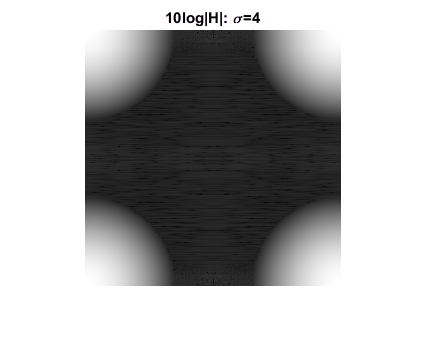


for m=1:256
    for n=1:256 
        h(m,n)=1/(2*pi*sigma^2)*exp(-((m-129)^2+(n-129)^2)/(2*sigma^2));
    end
end

h=fftshift(h);
H=fft2(h);

imshow(log10(abs(H)), []); 
title(['10log|H|: \sigma=4']);

(b) Process the “Lena” image in the frequency domain using the above $H[k, l]$. This will involve taking 2D-DFT of the image, multiplying the two DFTs and then taking the inverse of the product. Comment on the visual quality of the resulting filtered image. 

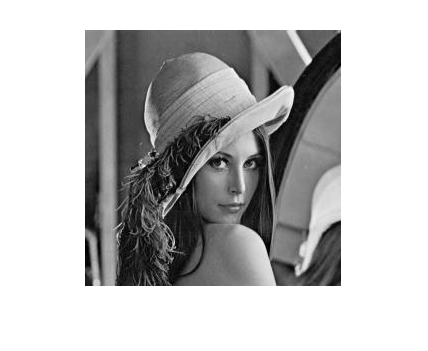

Lena=imread('lena.jpg');
imshow(Lena);

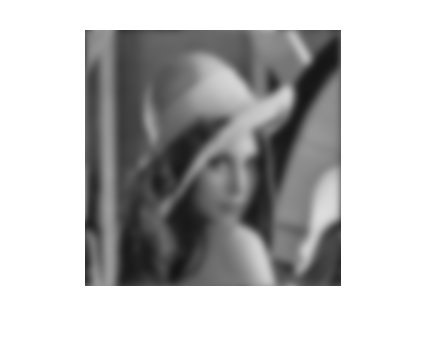


L=fft2(Lena);
X=L.*H;
x=ifft2(X)/255;
imshow(x);

(c) Repeat (a) and (b) for $σ = 32$ and comment on the resulting filtered image as well as the difference between the two filtered images. 

h1=zeros(256);
sigma=32

sigma = 32

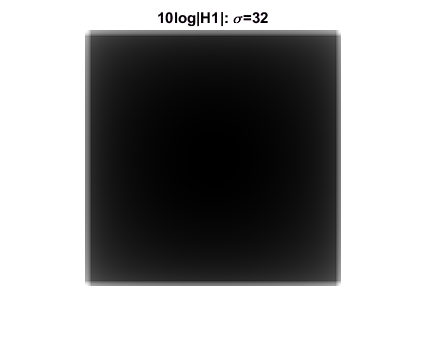


for m=1:256
    for n=1:256 
        h1(m,n)=1/(2*pi*sigma^2)*exp(-((m-129)^2+(n-129)^2)/(2*sigma^2));
    end
end

h1=fftshift(h1);
H1=fft2(h1);

imshow(log10(abs(H1)), []); 
title(['10log|H1|: \sigma=32']);

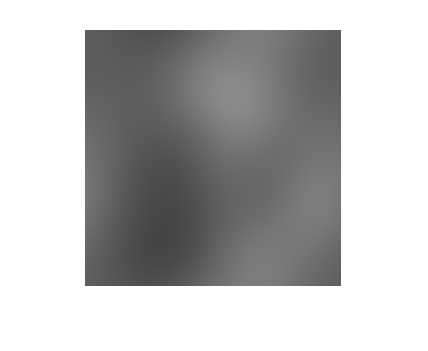


X1=L.*H1;
x1=ifft2(X1)/255;
imshow(x1);

(d) The filtered image in part (c) also suffers from an additional distortion due to a spatial domain aliasing effect in the circular convolution. To eliminate this artifact, consider both the image and the filter $ h[m, n]$ as 512 × 512 size images using zero-padding in each dimension. Now perform the frequency-domain filtering and comment on the resulting filtered image. 

h2=zeros(512);
sigma=32

sigma = 32

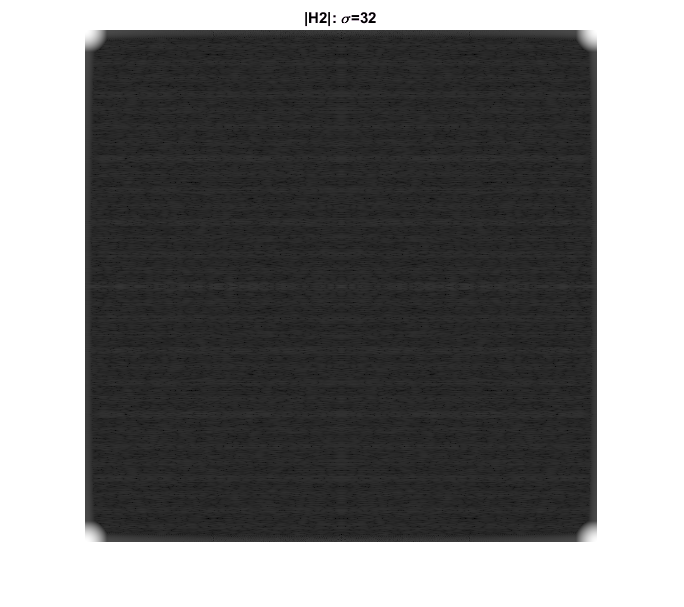


for m=1:512
    for n=1:512
        h2(m,n)=1/(2*pi*sigma^2)*exp(-((m-257)^2+(n-257)^2)/(2*sigma^2));
    end
end

h2=fftshift(h2);
H2=fft2(h2);

imshow(log10(abs(H2)), []); 
title(['|H2|: \sigma=32']);

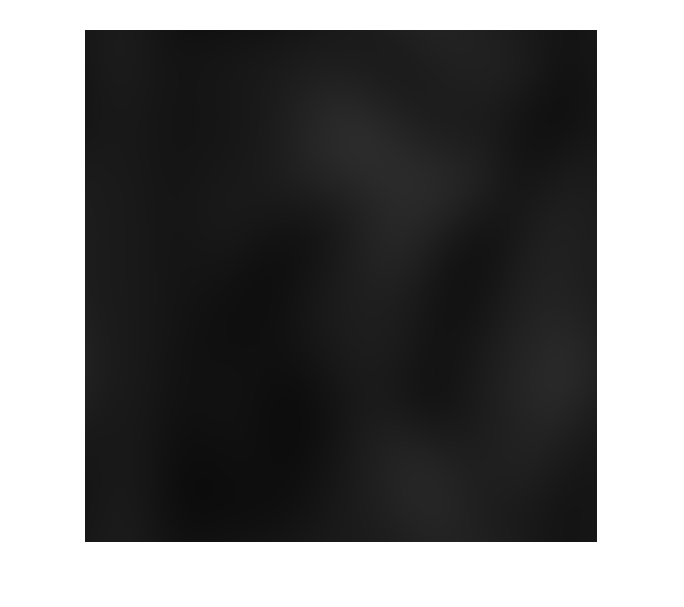


Lena2=zeros(512, 512);
m=1:2:512;
n=1:2:512;
Lena2(m, n)=Lena;

L2=fft2(Lena2);
X2=L2.*H2;
x2=ifft2(X2)/255;
imshow(x2);

(e) Repeat part (b) for $σ = 4$ but now using the frequency response$ 1 − H[k, l]$ for the filtering. Compare the resulting filtered image with that in (b). 

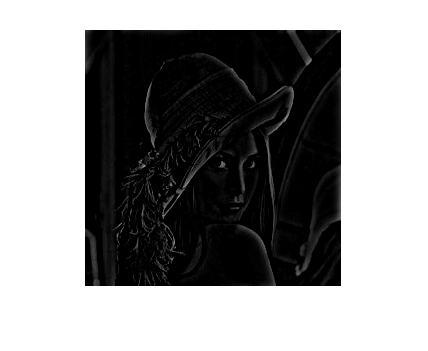

H3=ones(256)-H;

X3=L.*H3;
x3=ifft2(X3)/255;
imshow(x3);